close all
clc
clear

## Import data

X1 = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\光谱数据\氙灯反射.xlsx', 'X');
X2 = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\光谱数据\氙灯透射.xlsx', 'X');
Y = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\理化数据.xlsx', 'LYC');
Z = xlsread('D:\2ZYHfiles\实验数据汇总\实验数据汇总-按照时间和内容排序\20240531番茄红素颜色融合预实验\理化数据.xlsx', 'Z');

## Preprocessing and spectra combination

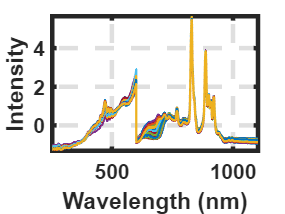

%Combination of transmittance and reflectance spectra
start_column1 = 100;
end_column1 = 846;
selected_columns1 = start_column1:end_column1;

start_column2 = 847;
end_column2 = 2000;
selected_columns2 = start_column2:end_column2;

X1tmp = X1(:, selected_columns1);
Z1tmp = Z(start_column1:end_column1);
X2tmp = X2(:, selected_columns2);
Z2tmp = Z(start_column2:end_column2);

X1tmp=snv(X1tmp);
X2tmp=snv(X2tmp);

X = [X1tmp, X2tmp];
Z = [Z1tmp; Z2tmp];


figure
ROW=size(X,1);
for i = 1:ROW
    plot(Z,X(i,:), 'LineWidth', 1.5)
    %plot(Z,X1(i,:), 'LineWidth', 1.5,'Color','#4169E1') #Check spectra X1
    %plot(Z,X2(i,:), 'LineWidth', 1.5,'Color','#FF6347') #Check spectra X2
    hold on
end
IntensityFigure();
hold off

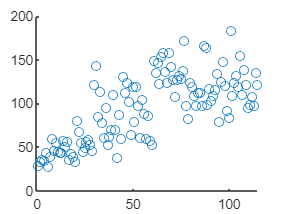


figure
scatter(1:length(Y), Y);

## Spectra sorted in descending order by the Y value

SD=std(Y, 1);
[row,col]=size(X);
Data=[Y X];
Data=sortrows(Data,-1);
Y=Data(:,1);
X=Data(:,2:(col+1));
X_raw=X;
Y_raw=Y;

## Spectra Feature Enhancement

% Enhanced wavelength range
ranges = [490 560; 610 760];
interval = 1;
% Initialize the enhanced spectral X and wavelength Z_new
Xen= X_raw;
Z_new = Z;

% Traverse each wavelength range
for i = 1:size(ranges, 1)
    range = ranges(i, :);
    % Generate interval points within the range
    new_wavelengths = range(1):interval:range(2);
    avg_values = zeros(size(X, 1), length(new_wavelengths));
    for j = 1:length(new_wavelengths)
        indices = find(Z >= new_wavelengths(j) & Z < new_wavelengths(j) + interval);
        if ~isempty(indices)
            avg_values(:, j) = mean(X(:, indices), 2);
        end
    end
    % Append the value to the enhanced spectral matrix
    Xen = [Xen, avg_values];
    Z_new = [Z_new; new_wavelengths'];
end

## Model development using PLS

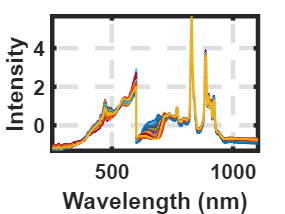

figure
for i = 1:ROW
    plot(Z,X(i,:), 'LineWidth', 1.5)
    hold on
end
IntensityFigure();
hold off

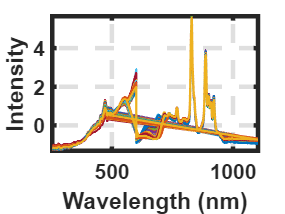


figure
for i = 1:ROW
    plot(Z_new,Xen(i,:), 'LineWidth', 1.5)
    hold on
end
IntensityFigure();
hold off

FinalResult=[];
num=0;
cnt = 0;

Y=Y_raw;
X=Xen;

while cnt<1

        % Data set division
        TestRatio=1/3;
        TrainNum=round(row*(1-TestRatio));
        
        %Data_Label=RandomSampleDivision(X,Y);
        Data_Label=descendingorder_extraction(X,Y,TestRatio);
        %Data_Label=ks_modification(X, Y, TrainNum);
        %Data_Label=SPXY_modification(X,Y,TrainNum); 
        
        %Modeling process
        SDc=std(Data_Label.target_train, 1);
        SDp=std(Data_Label.target_test, 1);
        CV = plscv(Data_Label.spec_train,Data_Label.target_train,8,10);
        PLS=pls(Data_Label.spec_train,Data_Label.target_train,CV.optLV);
        [ypred,Rp2,RMSEP]=plsval(PLS,Data_Label.spec_test,Data_Label.target_test,CV.optLV);
        RPD=SDp/RMSEP;
        CPI=3^(Rp2+(RPD-3)/3-abs(RMSEP/PLS.RMSEC-1));
        
        %Modeling results
        ModelingResult=[num,PLS.Rc2,PLS.RMSEC,Rp2,RMSEP,RPD,CPI];
    
        num=num+1;
        FinalResult(num,:)=ModelingResult;

        cnt = cnt+1;
end

The 1th group finished.
The 2th group finished.
The 3th group finished.
The 4th group finished.
The 5th group finished.
The 6th group finished.
The 7th group finished.
The 8th group finished.
The 9th group finished.
The 10th group finished.



FinalResult=sortrows(FinalResult,4,'descend');
